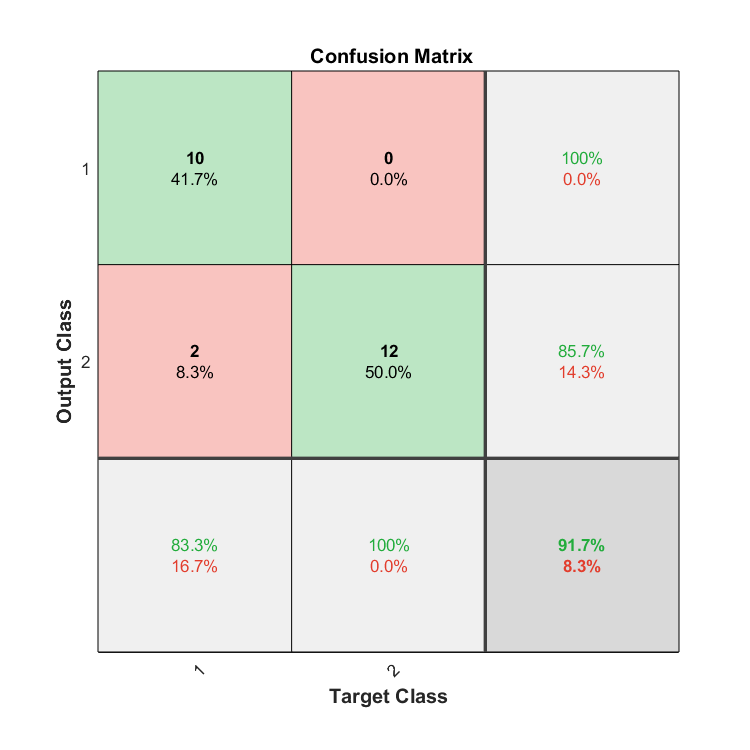

%For loop of task 1

% Load dataset
load Data_UCI_EPO4.mat;

Sel = [1,13]; % Two random features
X = [N1(:,Sel);Word1(:,Sel)]; 
% Data matrix for the selected features
Y = [zeros(40,1);ones(40,1)]; 
% Vector of labels, where 0 is the class N1 and 1the class Word 1
scatter(X(Y==0,1),X(Y==0,2))
hold on
scatter(X(Y==1,1),X(Y==1,2))
legend({'Number 1','Word 1'})

for i=1:3
    if (i == 1)
        sel1 = A;
    elseif (i == 2)
        sel1 = O;
    elseif (i == 3)
        sel1 = U;
    end
    for j=1:9
        switch j
            case 1
                sel2 = Word1;
            case 2
                sel2 = Word2;
            case 3
                sel2 = Word3;
            case 4
                sel2 = Word4;
            case 5
                sel2 = Word5;
            case 6
                sel2 = Word6;
            case 7
                sel2 = Word7;
            case 8
                sel2 = Word8;
            case 9
                sel2 = Word9;
        end
        
        % Data matrix for the selected words/vowels/numbers
X = [sel1;sel2]; 
Y = [ones(40,1);2*ones(40,1)]; 

percent_train_split=70/100;
train_id=[];
test_id=[];
num_classes=length(unique(Y)); 

% loop through the classes
for i=1:num_classes 
    % % finding the indices belonging to each class: use find()
    ind_i = find(Y==i);
    
    % %shuffling the indice
    ind_i_perm=ind_i(randperm(length(ind_i)));
    
    % % the split point for train test
    ind_split= percent_train_split * length(ind_i_perm);
    
    % % adding the train ids to the the previous ids 
    train_id= [train_id; ind_i_perm(1:ind_split)];
    
    % % adding the test ids to the the previous ids 
    test_id= [test_id; ind_i_perm(ind_split+1:length(ind_i_perm))]; 
    
    % % splitting the inputs
    % complete the codes below
    Xtrain= X(train_id,1:25);
    Xtest= X(test_id,1:25);

    % % splitting the labels
    Ytrain= Y(train_id,1);
    Ytest= Y(test_id,1);
    
    [Xtrain,mu_train,sigma_train] = zscore(Xtrain);
    
    Xtest= (Xtest-mu_train)./sigma_train;
    
    % This makes sure we get the same results every time we run the code.
    rng default

% How many trees do you want in the forest? 
    nTrees = 20;
 
% Train the TreeBagger (Random Forest).
    model = TreeBagger( nTrees,Xtrain,Ytrain ...
    , 'Method', 'classification');
    
    Ytest_pred_str = model.predict(Xtest);
Ytest_pred =  str2double(Ytest_pred_str);

Ytest_cat= zeros(num_classes,length(Ytest));
Ytest_pred_cat= zeros(num_classes,length(Ytest_pred));

for k=1:num_classes
    Ytest_cat(k, Ytest==k) = 1;
    Ytest_pred_cat(k, Ytest_pred==k) = 1;
end
    
    subplot(3,9,i+j)
plotconfusion(Ytest_cat, Ytest_pred_cat);
    
end
        
    end
end